## Reduced Order Modeling (ROM)

Model order reduction is a family of methods for creating surrogate models of large-scale systems. This interactive notebook introduces the Reduced Basis (RB) method a ROM technique with a strong mathematical ground that can be used to approximate solutions to Partial Differential Equations (PDEs) for real-time or multi-query applications. The RB method is used in this work to obtain a low-rank elasticity model to be used in a Digital Twin for real-time structural analysis.

**Note: **No third-party packages are needed for this script. Originally created on MATLAB 2022b

%% PROJECT CONFIGURATION %%
% Dependencies
addpath("include\")
% Parameters:
dir_model    = './../examples/Ex1_compliant_joint';      % Path to nodes and elements files.
dir_fea_data = './../examples/Ex1_compliant_joint/data'; % Path to high-fidelity simulation samples (snapshots).
partition_ratio = 0.2;      % Ratio of samples to be used in the rom
 

The main principle of the RB method is to divide the computational work into two stages:

- **Offline Stage - **It is the most intensive part of the method. It starts by parameterizing a system. Then by collecting snapshots of the system  on different states using a high-fidelity simulator. Finally, a set of basis and parameter reconstruction policies are determined in a systematic way.

- **Online Stage - **Using the Reduced-Order Basis (ROB) and parameter reconstruction policies from the offline stage, the original large-scale problem can now be approximated using new parameter values as inputs.

## Offline Stage

### Import Model's Data

The RB method is a data-driven framework. It parts from the assumption that a large-scale parameterized problem (for instance a system governed by a PDE) can be approximated as a linear combination of basis functionals, for which the cofficients show an affinity to the parameters. This statement will be divided into steps to have a clearer understanding of the method:

- Model parameterization.

- Data collection.

- Reduced Order Basis computation.

#### Step 1 - Model Parameterization

Let's assume we have a solid body with a particular shape (take **Fig. 1** as an example). A parameter can be any geometrical or physical feature we want to vary. Model parameterization consist on identifying the set of all parameters and their respective boundaries. The set of all input parameters is denoted by the $n-\textrm{dimension}$ vector $\mu$ and its boundaries by the subset $P\subset {\mathbb{R}}^n$. For instance, the model presented in **Fig. 1 **contains a single parameter $\left(n=1\right)$ which describes the lateral displacement (geomterical parameter) of the top-face of a compliant-joint, the displacement is bounded to $\pm 5\textrm{mm}$ (or $\mu \in \left\lbrack -5,5\right\rbrack \;\textrm{mm}=P$) meaning that $\mu$ can only take values inside that interval.

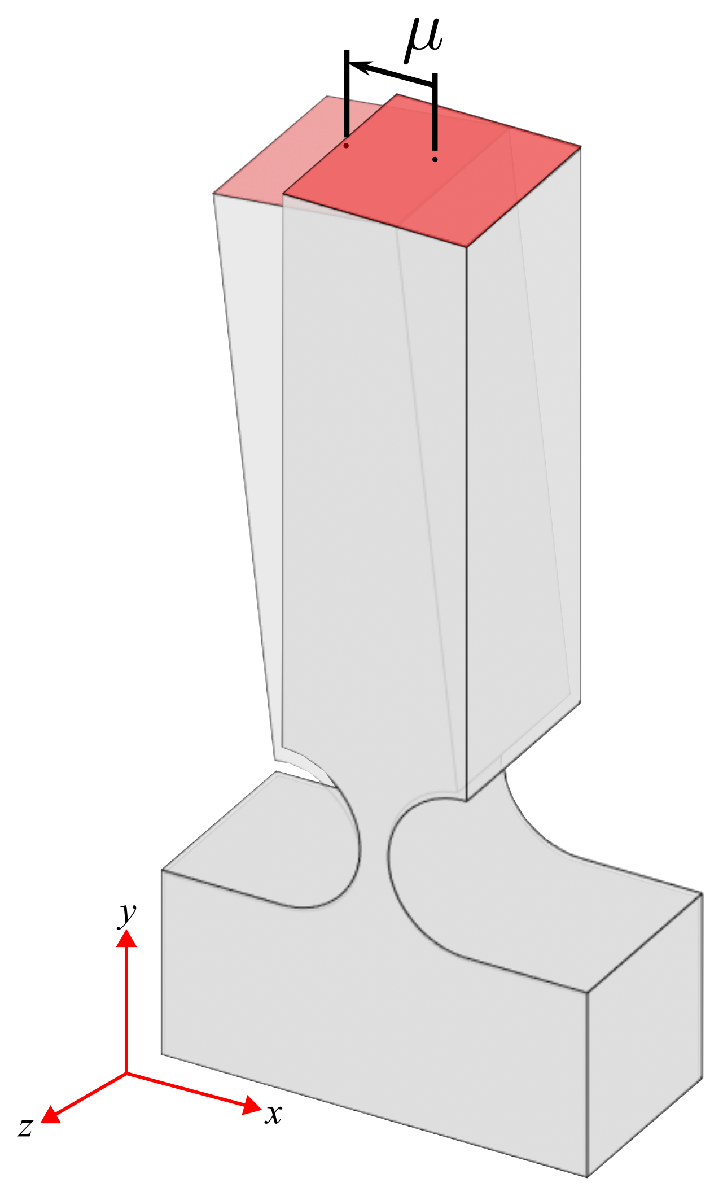

**Figure 1 -** Flexure-compliant joint with a single parameter $\left(\mu \;\right)$.

**Note: **The model parameterization can include design features as temperature, forces, dimensions, material's properties in any sort of combination. The important part is to clearly identify them as members of the vector $\mu$ and to consistnetly define their bounding limits in a realistic way.

#### Step 2 - Data Collection

Now that our system has been properly defined, we need to propose a data collection policy. First we need to decide what is the information that we need to know about our system, this could be for instance its density, its temperature, its stress, its deformation, its velocity (in the case of a fluid). If we are only interested in knowing the macroscopic properties of a system, like the velocity and position of a rigid body, then this might not be a proper modeling technique to use. In contrast, if we want to have a detailed and realistic view of the system, like knowing the exact shape of soft body when being actuated, then the RB method will be useful. We will call this kind of problems *large-scale* ones and most of the time they are associated to a governing equation in the form of a PDE. 

In the example from **Fig. 1 **the information to know is the stress and deformation when applying a displacement $\left(\mu \;\right)$. One way to model this phenomena is through the linear elasticity model (**Eq. 1**). SInce we are using a data-driven approach there is no need for analitically solve the PDE from **Eq. 1**. Actually the way to go is to use any well-known Finite Element Analysis software and take snapshots of the system under different $\mu$ values (**Fig. 2**).

$\nabla \cdot \sigma +f=0\;\;\;\;\textrm{in}\;\Omega$        (Eq. 1)

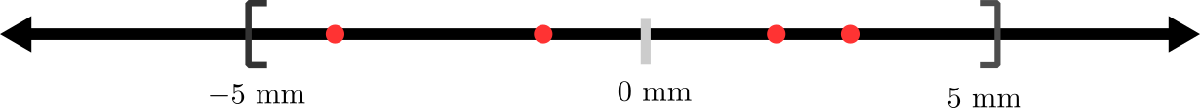

**Figure 2 - **Input parameter domain, $\mu \in \left\lbrack -5,5\right\rbrack \textrm{mm}$. The red dots represent the snapshots of the system under certain $\mu$ values. 

In our base example, several FEA simulations were done using ${\textrm{ANSYS}\;\textrm{Workbench}}^{\textregistered }$, in total 50 snapshots were taken with evenly spaced values of $\mu$. For our actual purpose there is no need to take 50 snapshots, taking just a few will be enought, the rest are used to validate the acurracy of the model and to show that taking different sets of snapshots will result in the same outcome.

**Note: **Format is crucial. 

% Import data
[ Nodes, ...            % Model's nodes in matrix format
  Elements, ...         % Model's elementes in matrix format
  CVonMises, ...        % Collection of VonMises snapshots (100%)
  CDisplacementX, ...   % Collection of x-displacement snapshots (100%)
  CDisplacementY, ...   % Collection of y-displacement snapshots (100%)
  CDisplacementZ, ...   % Collection of z-displacement snapshots (100%)
  CInputs, ...          % Collection of input parameters (100%)
  TrainSet, ...         % Set of index for offline stage (ratio)
  ValSet ...            % Set of index for online validation (1-ratio)
] = import_data( dir_model, dir_fea_data, partition_ratio );

% Slice training data
DisplacementX = CDisplacementX(:,TrainSet); % x-displacement
DisplacementY = CDisplacementY(:,TrainSet); % y-displacement
DisplacementZ = CDisplacementZ(:,TrainSet); % z-displacement
VonMises      = CVonMises(:,TrainSet);      % VonMises
u = CInputs(:,TrainSet);                    % Input parameters
n_u = length( CInputs ); 

### Model Visualization

Here you can check that your files have been imported properly. Each $\textrm{idx}$ value corresponds to one snapshot. This snapshots are all contained in a matrix (one for each variable). This matrix will be refered as the snapshot matrix (${\mathbb{S}}_u$), where the subindex indicates the variable that it contains:

- 
$$x-\textrm{displacement}\;\left(\delta_x \right)$$


- 
$$y-\textrm{displacement}\;\left(\delta_y \right)$$


- 
$$z-\textrm{displacement}\;\left(\delta_z \right)$$


- 
$$\textrm{Equivalent}\;\textrm{Von}\;\textrm{Mises}\;\textrm{stress}\;\left(\sigma_v \right)$$


The visualization combines this variables in a single 3D representation.

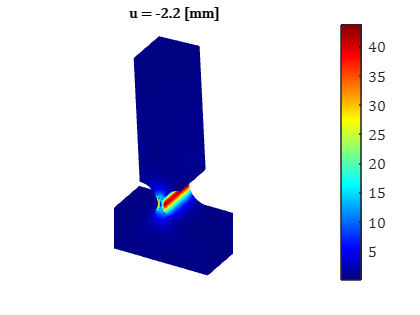

idx = 15;
deformation = [ CDisplacementX(:,idx), CDisplacementY(:,idx), CDisplacementZ(:,idx) ];
model_plot( Nodes + deformation', Elements, CVonMises(:,idx) );
title( "u = " + CInputs(idx) + " [mm]", "FontName", "Cambria Math" )

#### Step 3 - Reduced Order Basis (ROB) computation

A basis, in the context of linear algebra and functional analysis, is the name that we give to mathematical components that belong to certain space that can be linearly combined to create any other element of the space. For example $\hat{i} ,\hat{j}$ are canonical basis used frequently in physics to denote that some pehnomena is ocurring in a 2D space $\left(\vec{v} =12\;\hat{i} -8\;\hat{j} \right)$. A Reduced Order Basis (ROB) in the context of the RB method refer to mathematical objects that show affinity to their input parameters and can be linearly combined to approximate large-scale problems. Most of the time they can be used to physically interpret a system.

It is easier to understand the ROB concept when seen as an optimization problem. Given a collection of snapshots, the ROB of that collection will be the vector that best resembles all the elements of the collection. Proper Orthogonal Decomposition (POD) is a mathematical formulation that can accomplish this in a systematic way.

#### Proper Orthogonal Decomposition (POD)

The POD is just an specific use case for the Singular Value Decomposition (SVD), a matrix factorization widely use for data analysis. It has certain properties that simplify the computation of the ROB. Refer to [...] for further information on these properties. The important concepts to keep in mind are the following:

- The sanpshot matrix ($\mathbb{S}$) is formed by solution vectors ($u_h \left(\mu_i \right)$) as their columns. Which results in $\mathbb{S}$ being a tall-narrow matrix, with a number of rows equal to the number of nodes in the FEA mesh ($N_h$) and a number of columns equal to the number of snapshots ($N_s$). The order in which the columns are presented doesn't matter.

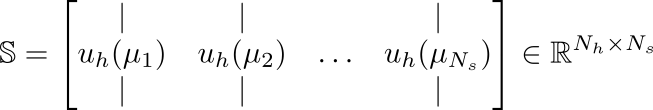 

**Figure 3 - **Visualization of the snapshot matrix ($\mathbb{S}$).

- The SVD generates three matrices, each of them has a an specific meaning. $\mathbb{U}$ is an orthogonal matrix that contains the ROB as their columns ($\zeta_i$). $\Sigma$ is a diagonal matrix that contains scalars ($\sigma_i$) that represent the importance of their respective ROB. ${\mathbb{Z}}^T$ is another orthogonal matrix which will be used later to relate the ROB with the input parameter $\left(\mu \right)$.

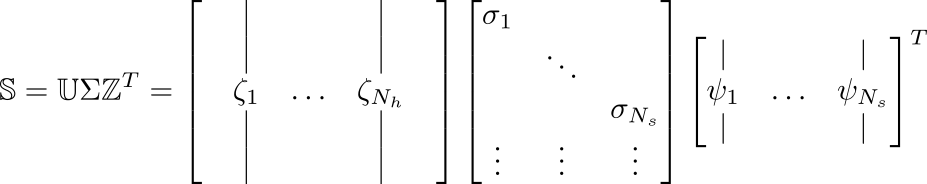

**Figure 4 -** Visualization of the Singular Value Decomposition.

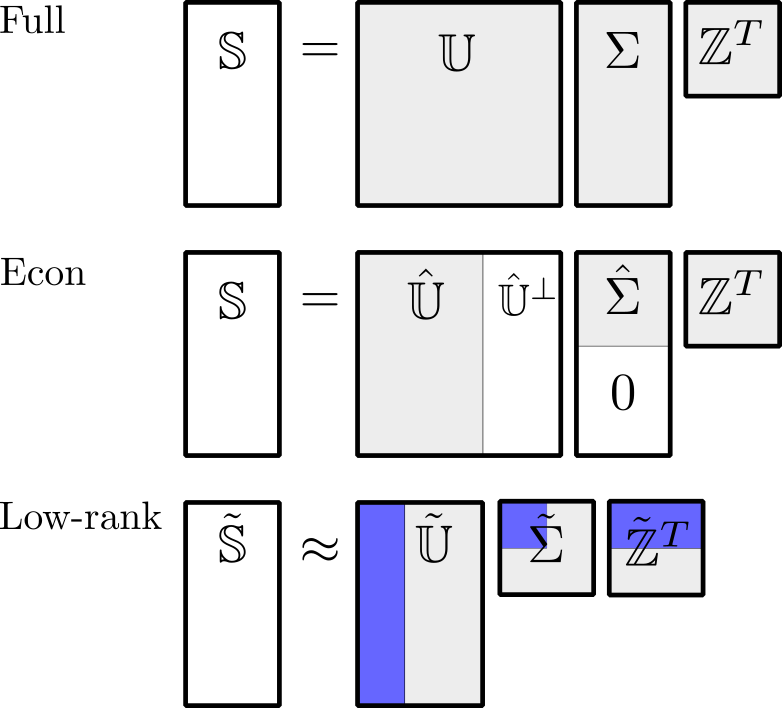

**Figure 5 **- Full-order representation of the SVD, economic representation of the SVD and low-rank approximation of the SVD.

- The number of ROB will be always be less or equal (most of the time equal) to the number of snapshots provided.

- Schmidt-Eckart-Young (SEY) theorem states that matrix $\mathbb{S}$ can be best approximated by a rank $L$ models that takes the first $L$-number of ROB. The error of the approximation can be estimated by $\varepsilon^2 =\frac{\sum_{j=L+1} \sigma_j^2 }{\sum_{j=1} \sigma_j^2 }$.

- Matrix $\mathbb{S}$ approximation can be formulated as a weighted sum of the effect of each basis (Eq. 2), therefore, each column of $\mathbb{S}$ can be expresed as a weighted sum as well.

$\mathbb{S}\simeq \tilde{\mathbb{S}} =\sum_{j=1}^L \sigma_j \zeta_j \psi_j^T \to u\left(\mu_i \right)\approx \sum_{j=1}^L \phi_j \left(\mu_i \right)\;\;\sigma_j \zeta_j$            $\psi_j^T =\left\lbrack \begin{array}{c}
\phi \left(\mu_1 \right)\\
\vdots \\
\phi \left(\mu_{N_s } \right)
\end{array}\right\rbrack$            (Eq. 2)

The first step of the POD is the SVD, the following script demostrates its use.

% Singular Value Decomposition
[Ux,Zx,Vx] = svd( DisplacementX, "econ", "vector" );
[Uy,Zy,Vy] = svd( DisplacementY, "econ", "vector" );
[Uz,Zz,Vz] = svd( DisplacementZ, "econ", "vector" );
[Uv,Zv,Vv] = svd( VonMises, "econ", "vector" );

#### Reduced Order Basis (ROB) - Visualization

It is easier to understand the underlying physics of the RB method when visualizing its ROB. The following script presents the ROB for each variable in a 3D representation.

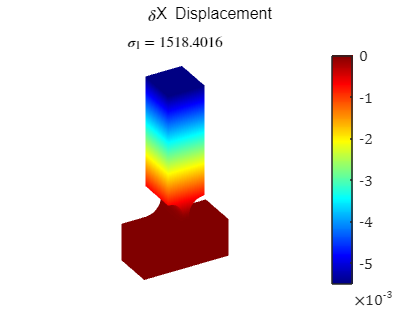

% Display first ROB on a grid.
grid_ = [1,1];

plotEigenPortraits( Nodes, Elements, Ux, Zx, grid_, [-30, 30] );
sgtitle( '\deltaX Displacement' )

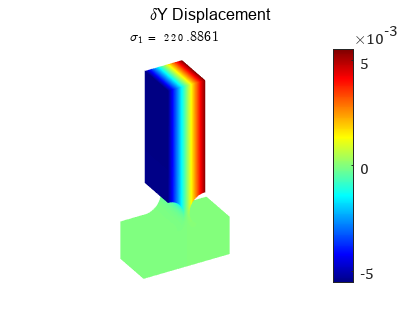


plotEigenPortraits( Nodes, Elements, Uy, Zy, grid_, [-30, 30] );
sgtitle( '\deltaY Displacement' )

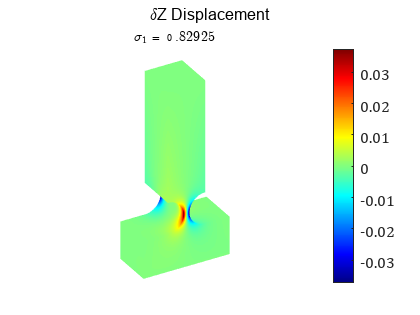


plotEigenPortraits( Nodes, Elements, Uz, Zz, grid_, [-30, 30] );
sgtitle( '\deltaZ Displacement' )

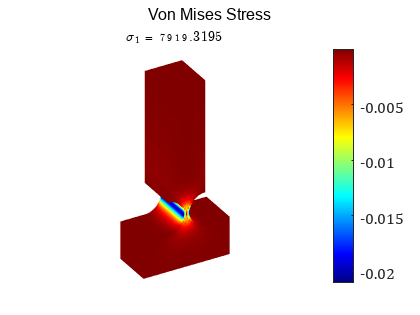


plotEigenPortraits( Nodes, Elements, Uv, Zv, grid_, [-30, 30] );
sgtitle( 'Von Mises Stress' )

**Note: **The respective $\sigma_j$ value indicates the importance of each ROB compared to the rest of basis. They are positive decreasing values, meaning that $\sigma_j \ge \sigma_{j+1} \ge 0$. For example, if $\sigma_1 =100$ and $\sigma_2 =0\ldotp 1$ it means that basis-$1$ is significantly more important than the rest. Next section shows this on a graph.

#### ROB - Error Estimation

Graphing the SEY error estimation:

$\varepsilon^2 =\frac{\sum_{j=L+1} \sigma_j^2 }{\sum_{j=1} \sigma_j^2 }$            (Eq. 3)

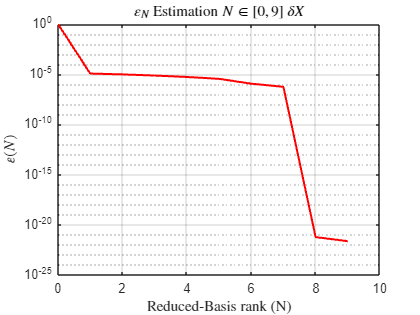

errorEstimationPlot( Zx, "$\delta X$" )

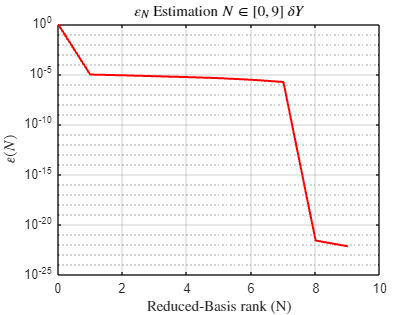

errorEstimationPlot( Zy, "$\delta Y$" )

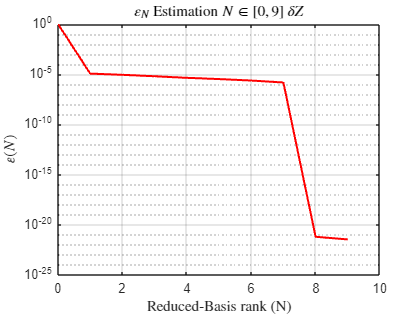

errorEstimationPlot( Zz, "$\delta Z$" )

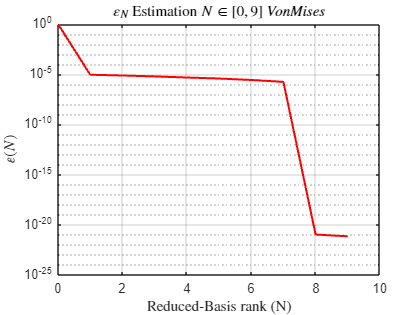

errorEstimationPlot( Zv, "$VonMises$" )


n_basis = length( u );

#### Step 4 - Parameter Reconstruction

The parameter reconsturction stage is the moment in which we create a way to relate our set of ROB and the input parameter. Up to this point we have only used the parameter-indepdent matrices of the SVD $\left(\mathbb{U},\Sigma \right)$, from which we have extracted the vectors $\zeta_j$ and the scalars $\sigma_j$ to use them as basis. The missing part is to assign a set of parameter-dependent coefficients to linearly combine with the ROB to construct a valid approximation of the system. The way to go is to use the knowledge that we have acquired up to this point. First we know that our final model should like a linear combination:


$$u\left(\mu \right)=\phi_1 \sigma_1 \zeta_1 +\ldots+\phi_L \sigma_L \zeta_L$$


We also know that $\sigma_j$ and $\zeta_j$ are fixed values that do not depend on $\mu$, thus the remaining coeffcients should depend on it. 


$$u\left(\mu \right)=\sum_{j=1}^L \phi_j \left(\mu \right)\;\sigma_j \zeta_j$$


From Eq. 2 we also know that there exists a way to relate $\phi_j \left(\mu \right)$ to known values of $\psi_j$. Such that $\psi_j =\left\lbrack \begin{array}{ccc}
\phi_j \left(\mu_1 \right) & \ldots & \phi_j \left(\mu_{N_s } \right)
\end{array}\right\rbrack$, since the input parameters $\left(\mu_i \right)$ are known the coefficient function $\left(\phi_j \right)$ can be interpolated for any basis. Fig. 6 illustrates this.

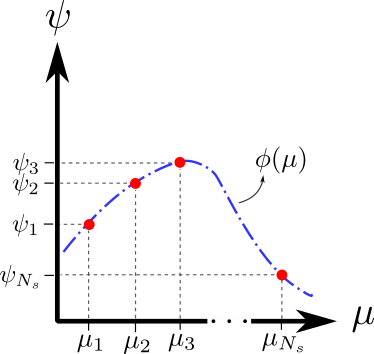

**Figure 6 -** Curve fit illustration as a least squares formulation.

% Scroll through the basis index to see how the coefficients map the input
% parameters for each variable.
basis_index = 3;

figure;
hold on;
grid on;

plot_sorted( [u,0], [Vx(:, basis_index)',0], ':o' )
plot_sorted( [u,0], [Vy(:, basis_index)',0], ':x' )
plot_sorted( [u,0], [Vz(:, basis_index)',0], ':+' )
plot_sorted( [u,0], [Vv(:, basis_index)',0], ':s' )

title ( "\textbf{Parameter reconstruction} ($\zeta_1$)", "Interpreter", "latex", "FontSize", 16 )
xlabel( "$\mu_i$", "Interpreter", "latex", "FontSize", 14 )
ylabel( "$\phi(\mu_i)$", "Interpreter", "latex", "FontSize", 14 )
xlim( [ min(CInputs), max(CInputs) ] )


#### Polynomial Curve Fit Example

This section shows a simple parameter reconstruction policy using a polynomial curve fit. Note that when the input parameters have high affinity, this reconstruction might be as simple as a linear interpolation otherwise, it might become as complex as it might need a machine learning model. The examples provided for this workshop were selected based on their affinity.

**Note:** Keep in mind that having non-linear or non-elliptic PDEs, multi-parameterization or poor parameter selection, and underfitting data might increase the complexity of the parameter reconstruction. 

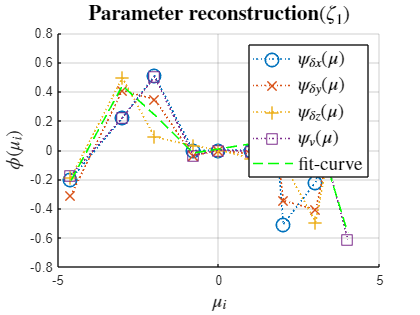

flag_cf     = true;                     % Activate curve fit visualization.
V_hat       = Vv;    % Select a variable to fit a curve.
curve_order = 4; % Select the polynomial curve order.
if flag_cf
    [a, X] = curve_fit( u', V_hat( :, basis_index ), curve_order );
    plot_sorted( u, (X * a)', "--g" )
    legend( ["$\psi_{\delta x}(\mu)$", "$\psi_{\delta y}(\mu)$", "$\psi_{\delta z}(\mu)$", "$\psi_{v}(\mu)$", "fit-curve"], "Interpreter", "latex", "FontSize", 14 )
else
    legend( ["$\psi_{\delta x}(\mu)$", "$\psi_{\delta y}(\mu)$", "$\psi_{\delta z}(\mu)$", "$\psi_{v}(\mu)$"], "Interpreter", "latex", "FontSize", 14 )
end

### Save Model

A reduced basis model is compact it can fit in a few Mb of memory.

**Note:** This section is fixed to save only the first basis information. Modify this section to your needs.

model_name = "Ex1_compliant_joint";
basis = [ Zx(1) * Ux(:,1), Zy(1) * Uy(:,1), Zz(1) * Uz(:,1), Zv(1) * Uv(:,1) ];
dirpath = "dump\" + model_name;
if ~exist(dirpath,'dir'), mkdir(dirpath); end
writematrix( basis, dirpath + "/basis.txt", "Delimiter", "tab" )
writematrix( a', dirpath + "/coefficients.txt", "Delimiter", "tab" )
 

### Load Model

model_name = "Ex1_compliant_joint";
basis = readmatrix( "./dump/" + model_name + "/basis.txt" );
a = readmatrix( "./dump/" + model_name + "/coefficients.txt" );
 

### Model Evaluation

Model evaluation depends entirely on the specific application it intends to serve. Here is an example of how easy and interactive it can be to use.

[model] = evalModel( a, basis );
input_parameter = -5;
[ deformation, Dv ] = model( input_parameter );

model_plot( Nodes + deformation', Elements, Dv );

fig = uifigure;
ax = uiaxes(fig, 'DataAspectRatio',[1,1,1], 'Visible','off', 'View', [30,30] );

h = graphic_engine( Nodes, Elements, Dv, ax );
sld = uislider(fig, 'Position',[40 350 150 3], 'ValueChangedFcn', @(sld,event) updateModel( sld.Value, h, Nodes', model ) );
sld.Limits = [-5,5];

### Sanity Check

Lastly, here we have a sanity check example, in which the RB model is tested against the validation set of snapshots (the ones that have not been used yet) to visualize the relative error (max, min, mean) for the equivalent stress variable, and residual (max, min, mean) for the displacement variables.

mu_set = CInputs( ValSet ); n = length( mu_set );
% Error Vectors
e_VonMises = zeros( n, 5 );
e_DisX = zeros( n, 5 );
e_DisY = zeros( n, 5 );
e_DisZ = zeros( n, 5 );

for j = 1 : n
     i = ValSet( j );
     % Reduced-Order Model Evaluation
     [ deformation, Dv ] = model( mu_set( j ) );
     % Full-Order Model Evaluation
     Dv_val = CVonMises(:,i);
     deformation_val = [ CDisplacementX(:,i), CDisplacementY(:,i), CDisplacementZ(:,i) ];
     % Equivalent Stress Relative Error
     e = 100 * abs( Dv - Dv_val ) ./ Dv_val;
     e_VonMises( j, : ) = [ mu_set( j ), mean( e ), max( e ), min( e ), std( e ) ];
     % Deformation Residual
     e = 100 * abs( deformation - deformation_val );
     e_DisX( j, : ) = [ mu_set( j ), mean( e(:,1) ), max( e(:,1) ), min( e(:,1) ), std( e(:,1) ) ];
     e_DisY( j, : ) = [ mu_set( j ), mean( e(:,2) ), max( e(:,2) ), min( e(:,2) ), std( e(:,2) ) ];
     e_DisZ( j, : ) = [ mu_set( j ), mean( e(:,3) ), max( e(:,3) ), min( e(:,3) ), std( e(:,3) ) ];
end

% Equivalent Stress Stats:
e_max_VonMises  = mean( e_VonMises(:,3) );
e_var_VonMises  = mean( e_VonMises(:,5) );
e_mean_VonMises = mean( e_VonMises(:,2) );

% X-displacement Stats:
e_max_DisX      = mean( e_DisX(:,3) );
e_var_DisX      = mean( e_DisX(:,5) );
e_mean_DisX     = mean( e_DisX(:,2) );

% Y-displacement Stats:
e_max_DisY      = mean( e_DisY(:,3) );
e_var_DisY      = mean( e_DisY(:,5) );
e_mean_DisY     = mean( e_DisY(:,2) );

% Z-displacement Stats:
e_max_DisZ      = mean( e_DisZ(:,3) );
e_var_DisZ      = mean( e_DisZ(:,5) );
e_mean_DisZ     = mean( e_DisZ(:,2) );

Name = [ "VonMises [%]", "x-displacement [mm]", "y-displacement [mm]", "z-displacement [mm]" ]';
Max  = [ e_max_VonMises, e_max_DisX, e_max_DisY, e_max_DisZ ]';
Var  = [ e_var_VonMises, e_var_DisX, e_var_DisY, e_var_DisZ ]';
Mean = [ e_mean_VonMises, e_mean_DisX, e_mean_DisY, e_mean_DisZ ]';

table( Name, Max, Var, Mean, 'VariableNames', ["Name", "Max", "Std. d.", "Mean"] )

figure;
hold on;
e = e_VonMises;
errorbar( e( :,1 ), e( :,2 ), e( :,4 ) - e( :,2 ) , e( :,2 ) - e(:,3), 'o' )
set( gca, 'YScale', 'log' );
